# Machine Learning with MATLAB

Digital Twin & Automation

# SVM Classification 

## Example1: Circular Distribution

### Dataset 1:  Random Generation for Circular Distribution

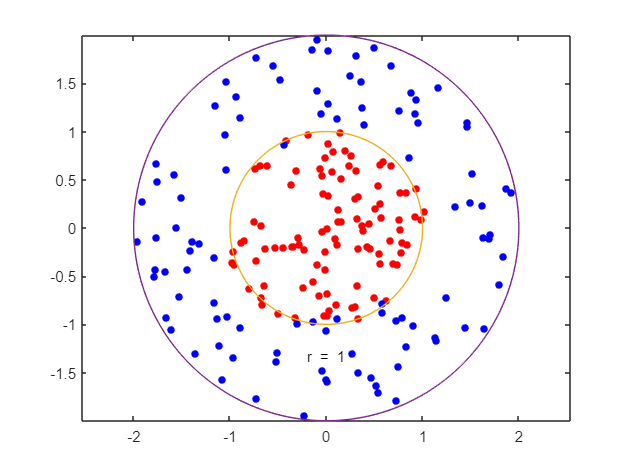

clear;

rng(1); % For reproducibility

% Class y=-1
r = sqrt(1.1 * rand(100,1));      % Radius
t = 2*pi*rand(100,1);             % Angle

data1 = [r.*cos(t), r.*sin(t)];   % Points

% Class y=1
r2 = sqrt(3 * rand(100,1)+0.9);   % Radius
t2 = 2*pi*rand(100,1);            % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points

% fitcsvm 함수에 넣어주기 위해 이어주기
dataC = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;

figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
ezpolar(@(x)1);ezpolar(@(x)2);
axis equal
hold off

### Train SVM 

% With Box Constraint =inf

cl = fitcsvm(dataC,theclass,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);

% With Box Constraint default
% cl = fitcsvm(dataC,theclass,'KernelFunction','rbf');


### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

mlResubErr = resubLoss(cl)

mlResubErr = 0

**Confusion matrix** on the training set

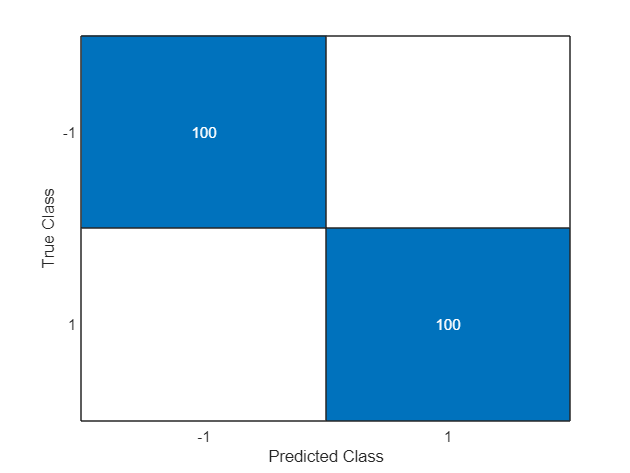

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(theclass,mlClass);

**Predict scores over the grid**

d = 0.02;

[x1Grid,x2Grid] = meshgrid(min(dataC(:,1)):d:max(dataC(:,1)),...
    min(dataC(:,2)):d:max(dataC(:,2)));

xGrid = [x1Grid(:), x2Grid(:)];

[~,scores] = predict(cl,xGrid);

**Plot the data and the decision boundary**

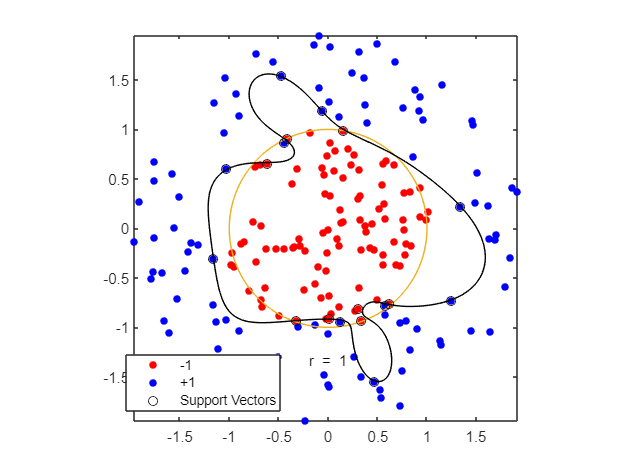

figure;

h(1:2) = gscatter(dataC(:,1),dataC(:,2),theclass,'rb','.');
hold on

ezpolar(@(x)1);

h(3) = plot(dataC(cl.IsSupportVector,1),dataC(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');

legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

rng(0)
cp = cvpartition(theclass,'KFold',10)  %k-fold

cp = K-fold cross validation partition
   NumObservations: 200
       NumTestSets: 10
         TrainSize: 180  180  180  180  180  180  180  180  180  180
          TestSize: 20  20  20  20  20  20  20  20  20  20

cvml = crossval(cl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0800

# Exercise  

## Exercise 1: SVM Classification with CWRU

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- For binary class:  Outer and Inner Race Fault

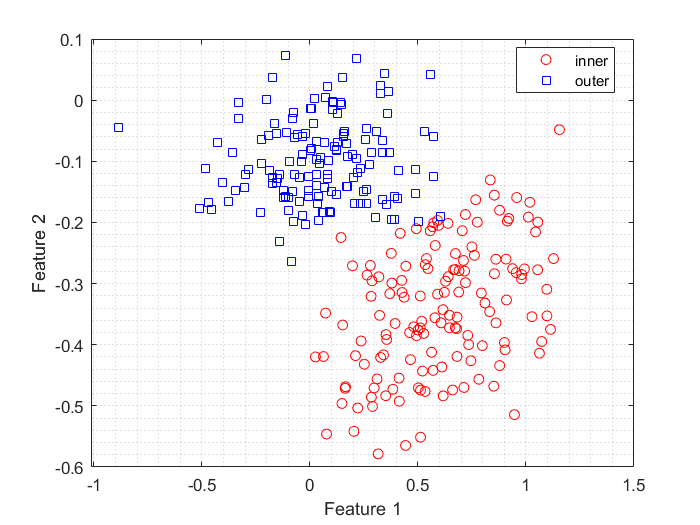

clear

% Eliminate clas 'normal'. Keep 'Inner', 'Outer'
load("../3_MachingLearning/CWRU_Datas/example_train.mat");

feature1 = "sv";                                            % skewness value of time data
feature2 = "ipf";                                           % impulse factor

Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));

Ytrain = class_cwru_train;                                  % fault class
classKeep = ~strcmp(Ytrain, 'normal');
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);
N = size(X,1);

% Plot
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
grid minor;
xlabel('Feature 1');
ylabel('Feature 2');

### **CV Partition**

% cvpartition to generate 10 disjoint stratified subsets.
cv = cvpartition(Y, 'KFold', 10)

cv = K-fold cross validation partition
   NumObservations: 288
       NumTestSets: 10
         TrainSize: 260  259  259  259  259  259  259  259  259  260
          TestSize: 28  29  29  29  29  29  29  29  29  28

###  Train SVM 

% specifiy class name:  fitcsvm(..., 'ClassNames',{'outer','inner'})
cl = fitcsvm(X, Y, 'KernelFunction', 'rbf', 'BoxConstraint', Inf, 'ClassNames', {'outer','inner'});
% cl =  fitcsvm(X, Y,'KernelFunction','rbf','ClassNames',{'outer','inner'})
% cl =  fitcsvm(X, Y,'ClassNames',{'outer','inner'})

### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

mlResubErr = resubLoss(cl)

mlResubErr = 0

**Confusion matrix** on the training set

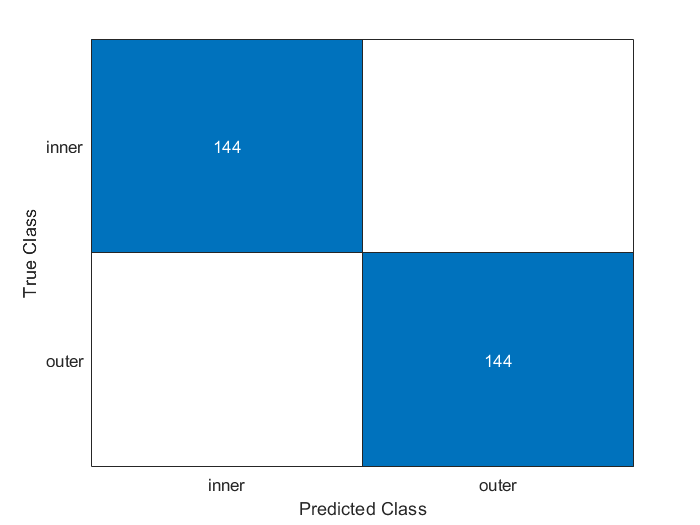

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(Y, mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];

[~,scores] = predict(cl,xGrid);

**Plot the data and the decision boundary**

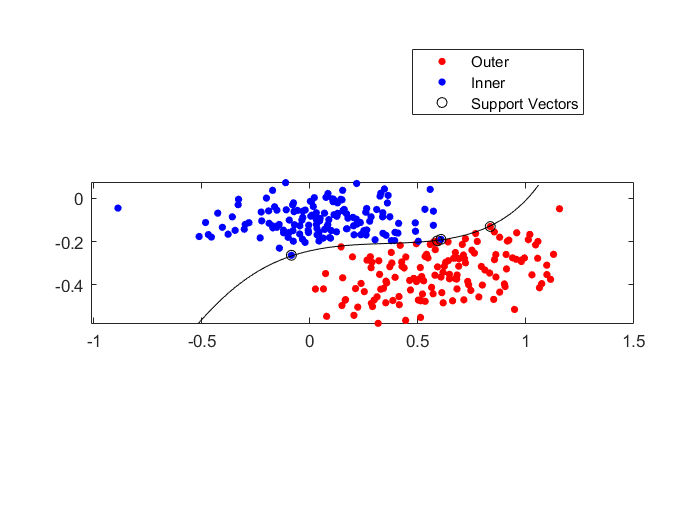

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y,'rb','.');
hold on

h(3) = plot(X(cl.IsSupportVector,1),X(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'Outer','Inner','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

rng(0)
cp = cvpartition(Y,'KFold',10)              %k-fold

cp = K-fold cross validation partition
   NumObservations: 288
       NumTestSets: 10
         TrainSize: 260  259  259  259  259  259  259  259  259  260
          TestSize: 28  29  29  29  29  29  29  29  29  28

cvml = crossval(cl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0174

Cross validate and show cv loss

## Exercise 2: CWRU 

Now, Use all 3 classes:  normal,  outer, inner.  Apply Multi_Class SVM 

**Features**

% Example
% X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
% X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
% X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

clear

% TRAIN
load('../3_MachingLearning/CWRU_Datas/example_train.mat')

feature1 = "kv";       
feature2 = "mf";        
feature3 = "cf";      

Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));
Xtrain(:, 3) = table2array(glob_all_train(:, feature3));

% TEST SET
load("../3_MachingLearning/CWRU_Datas/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Xtest(:, 3) = table2array(glob_all_test(:, feature3));
Ytest = class_cwru_test;

Ytrain = class_cwru_train;       

X = Xtrain;
Y = Ytrain;
N = size(X,1);

Analyze  the test and train results 

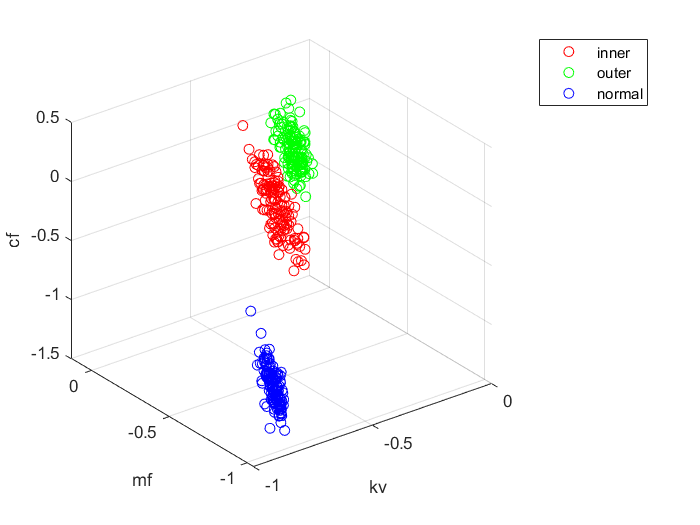

yCate = categorical(Y);
idx_inner = yCate == 'inner';
idx_outer = yCate == 'outer';
idx_normal = yCate == 'normal';

figure
plot3(X(idx_inner,1),X(idx_inner,2),X(idx_inner,3),'ro')
hold on
plot3(X(idx_outer,1),X(idx_outer,2),X(idx_outer,3),'go')
plot3(X(idx_normal,1),X(idx_normal,2),X(idx_normal,3),'bo') 
grid on
xlabel('kv')
ylabel('mf')
zlabel('cf')
legend('inner','outer','normal')
hold off

## CV Partition

% K-Fold method
cv = cvpartition(Y,'KFold',10)  

cv = K-fold cross validation partition
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

## **Training : SVM**

% To create a template for an SVM classifier
% Option 1 : specifies that the SVM classifier should standardize the training data before fitting the model.
% Option 2 : specifies that the SVM classifier should save the support vectors used in the model.
t = templateSVM('Standardize',true,'SaveSupportVectors',true);

% To train an SVM classifier 
% Train a multo class SVM classifier using the Error-Correcting Output code method
Mdl = fitcecoc(X,Y,'Learners',t,'ClassNames',{'inner','outer','normal'});

CVMdl = crossval(Mdl); 

genError = kfoldLoss(CVMdl)

genError = 0

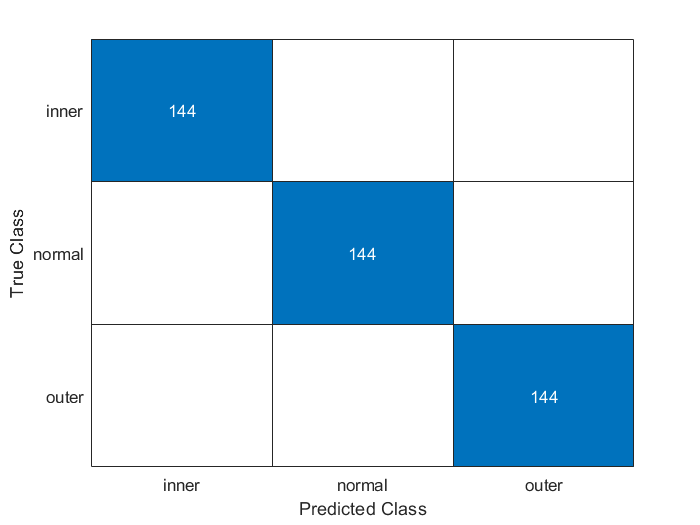

mlClass = resubPredict(Mdl);

figure
ldaResubCM = confusionchart(Y,mlClass); 

## **Test set : performance test of SVM model**

[label, score] = predict(Mdl, Xtest);
cnt = 0

cnt = 0

% FOR CHEKING
for IDX = 1 : length(label)

    comp = ~strcmp(Ytest(IDX), label(IDX));
    
    if(comp == 1)

        cnt = cnt+1;
    end
end

if(cnt == 0)

    disp('All individual datas are properly predicted...!')
end

All individual datas are properly predicted...!


## Exercise 3 

- Comparing the performance of Logistic regression, LDA, QDA is commented in prior file 'IAIA_MachineLearning_LDA_QDA.mlx'.

 Discussion (1) about SVM in exercise : Setting of BoxConstraint option

- -  In case where BoxConstraint option in function fitcsvm is set with 'default' value.    - In case where BoxConstraint option in function fitcsvm is set with 'INF' value.  

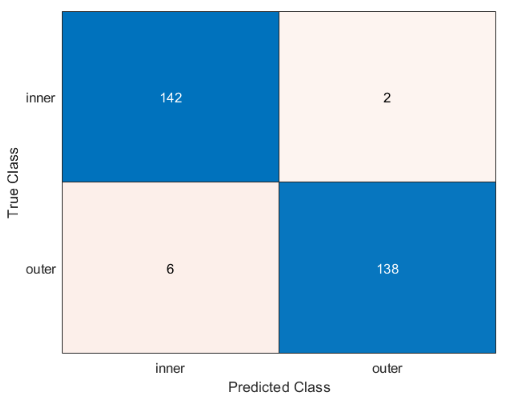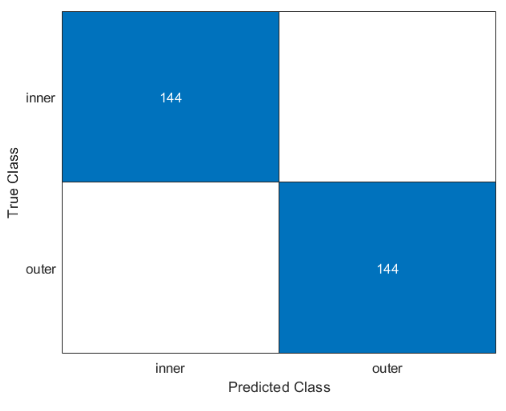

- The BoxConstraint parameter in the fitcsvm function is used to control the trade-off between achieving a small training error and a large margin. It sets an upper bound on the sum of the absolute values of the coefficients in the SVM model.

        **SOFT MARGIN**

- By default, the BoxConstraint is set to 1, which means that the SVM model is penalized for any deviation from the margin or any misclassification of the training data. This can lead to overfitting, where the model fits the training data too closely and fails to generalize well to new, unseen data.

- It may work better with noisy data.

- This can lead to underfitting, where the model fails to capture the underlying patterns in the data and performs poorly on new data.

         **HARD MARGIN**

- On the other hand, setting the BoxConstraint to Inf removes the regularization penalty, allowing the SVM model to fit the training data perfectly, even if this results in a smaller margin. This can lead to underfitting, where the model fails to capture the underlying patterns in the data and performs poorly on new data.

- In this case, the model is more likely to overfit the data, which can lead to poor generalization performance.

 Discussion (2) about SVM in exercise : Meaning of score of prediction

- Each row of Scores contains 3 scores. The size of score : (Length of  test array size) x (number of class)

- The index of the element with the maximum score is the index of the class to which the new class observation most likely belongs.

- When interpreting negative scores, it is important to keep in mind that the SVM model is designed to find the optimal decision boundary that maximizes the margin between the classes.